clear; close all; clc; tic;
%number of bits
bit_number=10^6; 
%generating random bits
data=randn(1,bit_number)>0.5; 
%generating BPSK signal
bpsk_data=2*data-1;    
%generating noise with zero mean and var. equal to 1.
noise=1/sqrt(2)*(randn(1,bit_number)+1i*randn(1,bit_number)); 
mean(abs(noise.^2)) %test the power of the noise 

ans = 1.0002

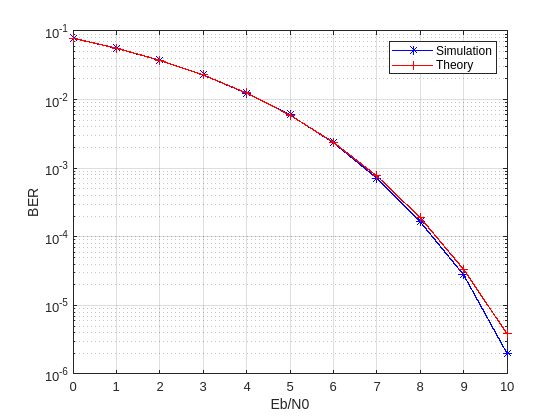

Elapsed time is 0.658130 seconds.


SNR=0:10;   %set SNR in dB
snr_lin=10.^(SNR/10); %calculate linear snr from dB SNR.
y=zeros(length(SNR),bit_number);
 %multiply sqrt of snr to signal and add noise:
for i=1:length(SNR)
    y(i,:)=real(sqrt(snr_lin(i))*bpsk_data+noise);
end
%reciever and ber count
err=zeros(length(SNR),bit_number); Err=zeros(10,2); 
for i=1:length(SNR)
    for j=1:bit_number
       if y(i,j)>=0
           y(i,j)=1;
       else
           y(i,j)=0;  
       end 
    end
      err(i,:)=abs(y(i,:)-data);
      Err(i,:)=size(find(err(i,:)));
end
 %calculating BER
ber=zeros(length(SNR),1);
for i=1:length(SNR)
    ber(i)=Err(i,2)/bit_number;
end
%theoretical BER calculation
theoryBer = 0.5*erfc(sqrt(snr_lin)); 
semilogy(SNR,ber,'b*-','linewidth',1); grid on;  hold on;
semilogy(SNR,theoryBer,'r+-','linewidth',1); grid on;  
xlabel('Eb/N0'); ylabel('BER'); legend('Simulation','Theory') ; toc;